## Marcel Fernández - Nia 252979

## Alejandro Pastor - Nia 253563

## Problema 1

% Leemos el dataset
num = readmatrix('SM_GaitAnalysis_4.xlsx')

num =        NaN    0.4700    0.1300    1.1120
       NaN    0.4800    0.1300    1.1000
       NaN    0.4400    0.0900    1.3300
       NaN    0.4200    0.1200    1.0480
       NaN    0.3700    0.1500    0.9740
       NaN    0.4000    0.1500    0.9220
       NaN    0.4600    0.1100    0.9930
       NaN    0.4190    0.0990    1.3500
       NaN    0.4300    0.1500    1.0370
       NaN    0.4800    0.1300    0.9510


**a)  State the null and alternative hypotheses for this problem:**

En este caso, queremos probar si, en promedio, las mediciones de tiempo y velocidad difieren según una cierta división de estos pacientes, así que:

Null Hypothesis            --> H0 : tau_L = 0 for all L = 1,..., g

Alternative Hypothesis --> Ha : Exists at least a L that   tau_L != 0

Donde  Tau_l = mu_l - mu			

**b) Indicate what method would you use to answer the research questions of this Problem. 						**				

Dado que nos encontramos en el caso de 4 poblaciones con 3 dimensiones en cada muestra (multivariado), necesitamos utilizar **MANOVA** (Análisis de Varianza Multivariado) calculando el Lambda de Wilks, transformándolo en una estadística F y evaluando la hipótesis nula.

**c) If your method requires uni- or multi-variate normality in any way, assess whether the data fulfills such assumption(s), at significance level α = 0.05. Make sure to state your conclusion. 	**					

Para observar la normalidad inicialmente haremos un QQ-plot para cada una de las diferentes variables de cada grupo. De esta manera, lo que haremos será verificar la "univariate normality". Para determinar si esta variable sigue una distribución normal, utilizaremos el coeficiente de correlación. Si el valor del coeficiente es menor que el valor crítico (obtenido de una tabla), podremos rechazar la hipótesis de normalidad y, por lo tanto, diremos que ese grupo ya no puede considerarse normalmente distribuido. Esto se debe a que si una única variable no sigue una distribución normal, entonces ya no habrá "multivariate normality".

En caso contrario, si el valor de correlación es mayor que el valor crítico, no podremos rechazar la hipótesis nula y, por lo tanto, la idea de normalidad se mantendrá.

Si los primeros QQ-plots indican que la normalidad se mantiene, procederemos a realizar los Chi-Plots. Estos implican crear combinaciones de dos dimensiones de cada grupo para determinar si existe "bivariate normality". Utilizaremos la misma técnica mencionada anteriormente para evaluar la normalidad en estas combinaciones.

En caso de que aún no hayamos rechazado la hipótesis de normalidad, pasaremos al último test, que será nuevamente un Chi-Plot, pero esta vez utilizando las tres variables. Si este test no rechaza la hipótesis de normalidad, podremos concluir que se cumple nuestra asunción de "Multivariate Normality".

% Vamos a guardar cada grupo con sus dimensiones respectivas
% Grupo A
gA = num(1:12,2:4);
gA_1 = gA(:,1);
gA_2 = gA(:,2);
gA_3 = gA(:,3);

% Grupo B
gB = num(13:35,2:4);
gB_1 = gB(:,1);
gB_2 = gB(:,2);
gB_3 = gB(:,3);

% Grupo C
gC = num(36:55,2:4);
gC_1 = gC(:,1);
gC_2 = gC(:,2);
gC_3 = gC(:,3);

% Grupo D
gD = num(56:81,2:4);
gD_1 = gD(:,1);
gD_2 = gD(:,2);
gD_3 = gD(:,3);

% Tenemos que hacer los QQ plots de cada grupo, con sus 3 dimensiones para
% poder verificar la normalidad de la variable

fprintf("qq-plot for group A")

qq-plot for group A

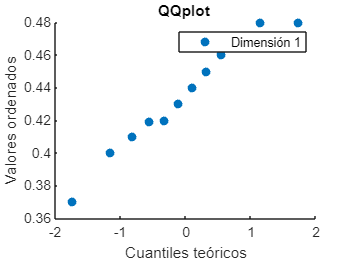

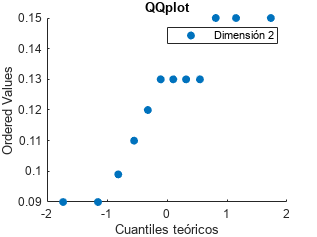

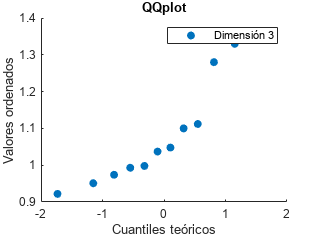

r1 = 0.9833

r2 = 0.9542

r3 = 0.9371

crearqqplot(gA_1,gA_2,gA_3)

fprintf("qq-plot for group B")

qq-plot for group B

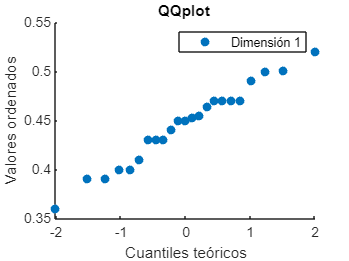

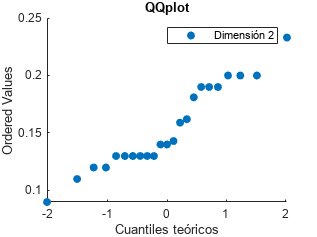

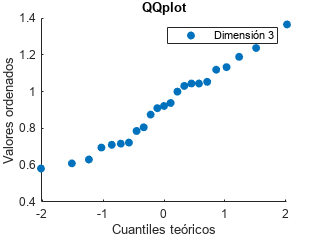

r1 = 0.9896

r2 = 0.9648

r3 = 0.9872

crearqqplot(gB_1,gB_2,gB_3)

fprintf("qq-plot for group C")

qq-plot for group C

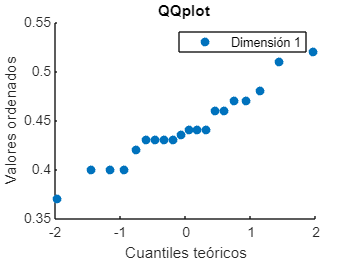

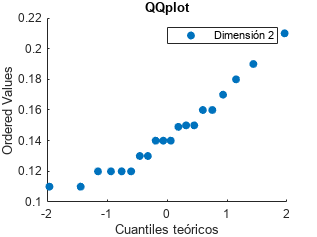

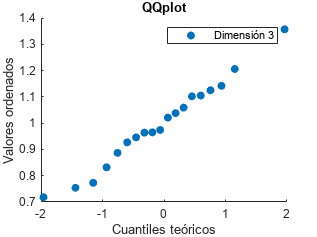

r1 = 0.9805

r2 = 0.9687

r3 = 0.9892

crearqqplot(gC_1, gC_2, gC_3)

fprintf("qq-plot for group D")

qq-plot for group D

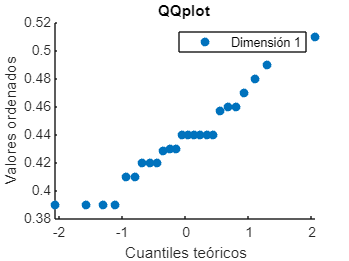

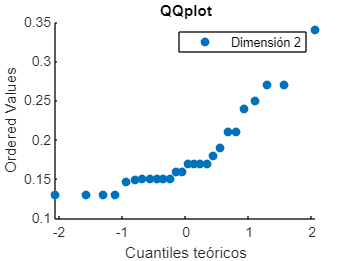

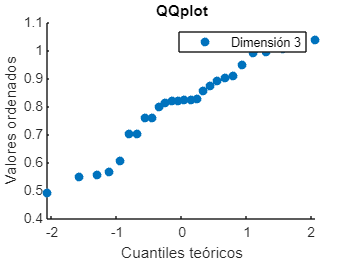

r1 = 0.9743

r2 = 0.9100

r3 = 0.9757

crearqqplot(gD_1,gD_2,gD_3)

Tabla de valores del coeficiente de correlación - nosotros usaremos **alpha = 0.05**

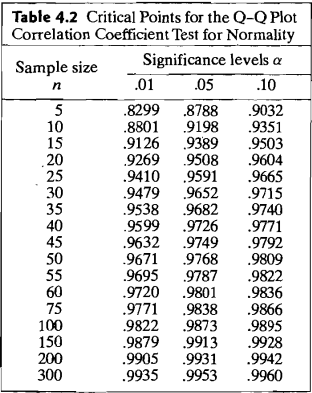

**Grup A: (nA_size = 12)**

En caso de que no tengamos el valor exacto en la tabla, utilizamos el valor de n = 10, ya que 12 está más cerca de 10 que de 15. Observamos** rcrit = 0.9198.** En este caso, podemos ver que si hubiéramos elegido el rcrit para n = 15, no podríamos haber rechazado la hipótesis nula (debido a la diferencia en los decimales). Por lo tanto, dado que 12 es menor que 15 y, además, es más conveniente para nuestro problema, utilizaremos n = 10 y no rechazaremos la hipótesis nula.

r1 =  0.9833 > 0.9198  ---  r2 = 0.9542 > 0.9198   ---  r3 = 0.9371 > 0.9198 

Por lo tanto se **mantiene la hipotesi de normalidad.**

**Grup B: (nB_size = 23)**

Usamos n = 25 por la misma razón que en el grupo A. **rcrit = 0.9591.**

En este caso todas las 'r_obs' son más grandes que la rcrit por lo tanto no podemos rechazar la hipotestis nula y de momento se **mantiene la normalidad**.

r1 =  0.9896 > 0.95495 ---  r2 = 0.9648 > 0.95495 --- r3 = 0.9872 > 0.95495

**Grup C: (nC_size = 20)**

**rcritic C =  0.9508** en este caso si que podemos encontrar el valor en la tabla directamente, con lo cual podemos proceder hacer las comparaciones con cada dimension. En este caso todas las 'r_obs' son más grandes que la rcrit por lo tanto no podemos rechazar la hipotestis nula y de momento se **mantiene la normalidad**.

r1 =  0.9805 > 0.9508 --- r2 = 0.9687 > 0.9508 --- r3 = 0.9892 > 0.9508

**Grup D: (nD_size = 26)**

**rcrit = 0.9591 **ahora usamos este valor que es el de n= 25 porque es muy cercano, al comparar con las dimensiones del grupo D, podemos apreciar que la segunda dimension tiene una **r = 0.9100 < rcrit = 0.9591 ** con lo cual rechazamos  la hipotesis nula y a su vez la normalidad.

Finalmente, podemos ver que solo el grupo A,B,C ha pasado el test para cada dimensión, no obstante tenemos que hacer las comparaciones entre las variables y para ello usaremos **chi-square-plots. **

Únicamente realizaremos gráficos de chi-cuadrado (de **dos dimensiones**) para todos los grupos que cumplan con la "normalidad univariante". Por lo tanto, no realizaremos el gráfico para el grupo D, pero sí lo haremos para los demás grupos. Una vez que hayamos creado estos gráficos, podremos observar que hasta el momento no hemos podido rechazar la hipótesis de normalidad bivariante. Luego procederemos a hacer lo mismo con las tres dimensiones.

fprintf("CHI-SQUARE PLOT - Grupo A ")

CHI-SQUARE PLOT - Grupo A 

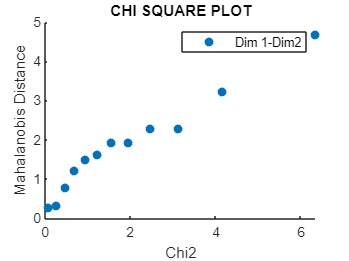

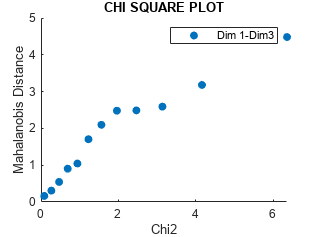

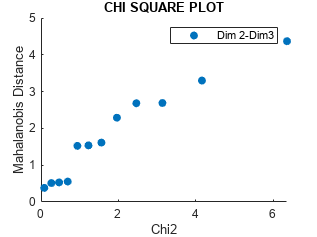

r1 = 0.9770

r2 = 0.9601

r3 = 0.9665

gA_12 = gA(:,1:2);
gA_13 = gA(:,[1,3]);
gA_23 = gA(:,2:3);
crearchiplot(gA_12,gA_13,gA_23)

fprintf("CHI-SQUARE PLOT - Grupo B ")

CHI-SQUARE PLOT - Grupo B 

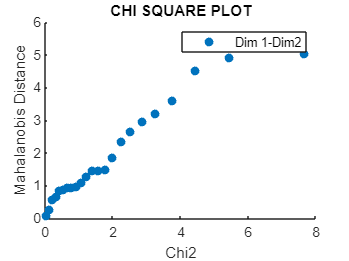

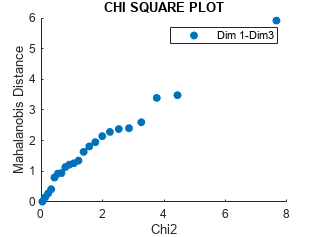

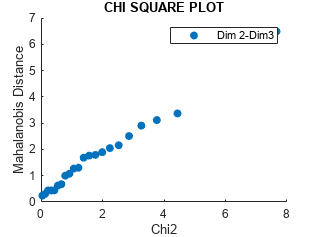

r1 = 0.9688

r2 = 0.9818

r3 = 0.9739

gB_12 = gB(:,1:2);
gB_13 = gB(:,[1,3]);
gB_23 = gB(:,2:3);
crearchiplot(gB_12,gB_13,gB_23)

fprintf("CHI-SQUARE PLOT - Grupo C ")

CHI-SQUARE PLOT - Grupo C 

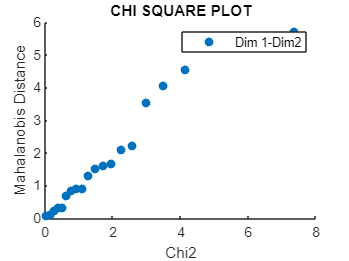

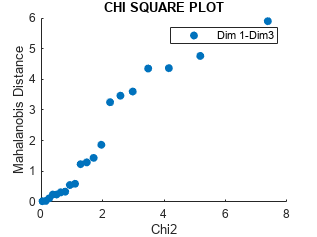

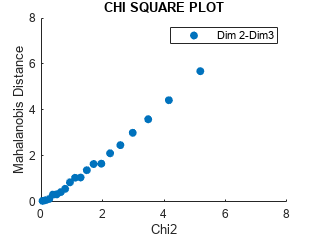

r1 = 0.9722

r2 = 0.9545

r3 = 0.9960

gC_12 = gC(:,1:2);
gC_13 = gC(:,[1,3]);
gC_23 = gC(:,2:3);
crearchiplot(gC_12,gC_13,gC_23)

Al hacer los gráficos de chi-square podemos observar que tienen una 'r' razonable y que mantinen el ángulo de 45grados respecto al eje, con lo cual si que van a tener pendiente ≈ 1, esto nos dice que sigue habiendo normalidad entre dimensiones.

Ahora solo necesitamos calcular el gráfico de chi-cuadrado para las 3 dimensiones de cada población de muestras:

fprintf("CHI-SQUARE PLOT - 3 dimensiones del grupo A")

CHI-SQUARE PLOT - 3 dimensiones del grupo A

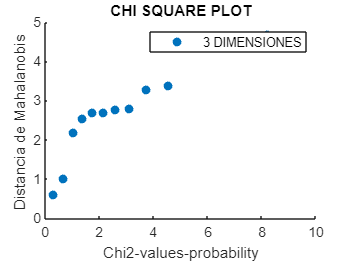

r1 = 0.9147

chi3dims(gA)


fprintf("CHI-SQUARE PLOT - 3 dimensiones del grupo B")

CHI-SQUARE PLOT - 3 dimensiones del grupo B

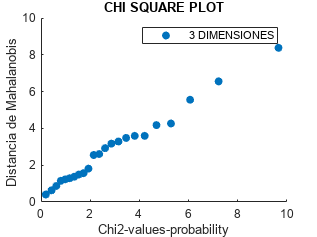

r1 = 0.9928

chi3dims(gB)


fprintf("CHI-SQUARE PLOT - 3 dimensiones del grupo C")

CHI-SQUARE PLOT - 3 dimensiones del grupo C

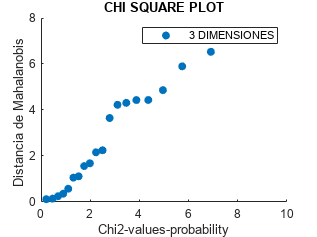

r1 = 0.9605

chi3dims(gC)

Como mencionamos previamente, hasta el momento los grupos A, B y C parecen seguir una distribución bivariante normal. Sin embargo, necesitamos verificar si las tres dimensiones juntas también cumplen con la normalidad multivariante. Para ello, realizaremos un gráfico de chi-cuadrado utilizando las tres dimensiones.

El resultado nos indica que debemos rechazar la hipótesis de normalidad multivariante para el grupo A. En consecuencia, los únicos grupos que presentan normalidad multivariante son B y C.

**d) If your method requires any assumptions regarding variances or covariances, assess whether the data fulfills such assumption(s). Make sure to state your conclusion. **		

Para comprobar si las matrices de covarianza son parecidas, usaremos el ratio **1/4 <= x <=4**. Lo que haremos sera comprobar que todos los elementos de las diagonales de las matrices, cuando calcumaos su ratio quede dentro del intervalo. Si el  valor queda fuera de este intervalo podemos decir que esas matrices NO son iguales, al contrario si el ratio queda dentro de el intervalo podremos decir que las matrices son parecidas (Lo que nos interesa para continuar con el problema)

% cov matrices
covA = cov(gA);
covB = cov(gB);
covC = cov(gC);
covD = cov(gD);

n = 3; 

ratios = zeros(6,n);

j = 1;
for i = 1:n
    ratios(j, i) = covA(i, i) / covB(i, i);
end
j = j + 1;
for i = 1:n
    ratios(j, i) = covA(i, i) / covC(i, i);
end
j = j + 1;

for i = 1:n
    ratios(j, i) = covA(i, i) / covD(i, i);
end
j = j + 1;

for i = 1:n
    ratios(j, i) = covB(i, i) / covC(i, i);
end
j = j + 1;

for i = 1:n
    ratios(j, i) = covB(i, i) / covD(i, i);
end
j = j + 1;

for i = 1:n
    ratios(j, i) = covC(i, i) / covD(i, i);
end
ratios

ratios =     0.7043    0.3590    0.4791
    0.8465    0.6514    0.7238
    0.9908    0.1727    0.9777
    1.2019    1.8146    1.5108
    1.4069    0.4810    2.0407
    1.1705    0.2651    1.3507


En la matriz de ratios, podemos observar todas las combinaciones de grupos y notamos que todos los ratios caen dentro del rango (1/4, 4). Por lo tanto, podemos concluir que las matrices de covarianza son similares, y, en consecuencia, nuestra suposición se cumple.

**e) Based on the results from (c) and (d), discuss whether the method selected in (a) can be applied or not. In case it cannot be applied because your data does not fulfill the required assumptions, try to fix it by choosing one of the following options (you are free to choose any of the above solutions, but the choice must be justified and you must justify also that, after applying the selected solution, your data now fulfills the required assumptions): **

**• Apply a transformation (e.g. see Section 4.8 from Johnson-Wichern’s book). **

**• Discard the patient group(s) that do not fulfill the assumptions.**

**• Identify and eliminate outliers. **	

Como hemos observado en los apartados anteriores: 

- Normalidad: Solo los grupos B y C la cumplen.

- Covarianza: Todos los grupos la cumplen.

Somos conscientes de que el método de eliminación no es el más adecuado, ya que podríamos intentar aplicar una transformación a los datos o eliminar algunos valores atípicos. Sin embargo, consideramos que es el método más "simple". El inconveniente de este enfoque es que implica la pérdida de una gran cantidad de información, pero al menos la información que retenemos es apropiada para llevar a cabo la siguiente prueba utilizando MANOVA. Por lo tanto, hemos decidido conservar únicamente los grupos que cumplen ambas suposiciones.

**f)  Apply the method selected in (a) to answer the research question, at significance level α = 0.05. if you performed any fixing in (e), then use the fixed data. Indicate your conclusions. 	**

En este caso , usamos MANOVA: 					

% first compute SStreat and SSres (B & W matrices)
X = [gB ; gC];
gB_ = mean(gB,1);
gC_ = mean(gC,1);
X_hat = mean(X,1);  

n2 = length(gB);
n3 = length(gC);

% Computations for B - Effects
tau2 = gB_ - X_hat;
tau3 = gC_ - X_hat;

B = n2*(tau2'*tau2) + n3*(tau3'*tau3);

% Residuals 
res2 = gB - gB_;
res3 = gC - gC_;


% Compute W
W = (res2'*res2)+(res3'*res3);

g = 2

g = 2

alpha = 0.05

alpha = 0.0500

% Wilks Lambda Calculation
dFb = g - 1;

N = n2 + n3;
dFw = N - g;

p = size(gB,2);
S = min(p,dFb);

dF1 = p * dFb;
dF2 = S * (dFw - ((p-dFb+1)/2)) - ((p*dFb-2)/2);

Wlambda = det(W) / det(B+W);

uppart = (1-Wlambda^(1/S))/ dF1;
downpart = (Wlambda^(1/S)) / dF2;
Fvalue = uppart / downpart

Fvalue = 1.0674


Fcrit = finv(1 - alpha, dF1, dF2)

Fcrit = 2.8451

**Fvalue = 1.0674 < 2.8451 = Fcrit**					

Una vez realizado el test, disponemos del valor crítico y el valor observado. Al compararlos, notamos que val_obs < val_crit, por lo tanto, no podemos rechazar la hipótesis nula expuesta en el apartado a). En consecuencia, podemos afirmar que ambos grupos (Grupo B y Grupo C) son iguales 

function crearqqplot(dim1,dim2,dim3)
    % primero de todo ordenamos los valores
    var1 = sort(dim1);
    var2 = sort(dim2);
    var3 = sort(dim3);
    n = size(var1,1);
    prob = zeros(n,1);
    % asignamos las probabilidades
    for j = 1:n
        prob(j,1) = (j-0.5)/n;
    end
    cuant = norminv(prob);
    
    figure
    scatter(cuant, var1, 'filled');
    xlabel('Cuantiles teóricos');
    ylabel('Valores ordenados');
    legend('Dimensión 1');
    title('QQplot ');
    figure
    scatter(cuant, var2, 'filled');
    xlabel('Cuantiles teóricos');
    ylabel('Ordered Values');
    legend('Dimensión 2');
    title('QQplot');
    figure
    scatter(cuant, var3, 'filled');
    xlabel('Cuantiles teóricos');
    ylabel('Valores ordenados');
    legend('Dimensión 3');
    title('QQplot');
    
    % Calculamos la R - coeficiente de correlacion
    r1 = corr(var1,cuant)
    r2 = corr(var2,cuant)
    r3 = corr(var3,cuant)
end

function crearchiplot(dim1_2,dim1_3,dim2_3)
    % compute mahalanobis distance between pairs of dimensions: 
    
    d_1_2 = mahalanobis2(dim1_2);
    d_1_3 = mahalanobis2(dim1_3);
    d_2_3 = mahalanobis2(dim2_3);
    

    % sort them
    d_1_2 = sort(d_1_2);
    d_1_3 = sort(d_1_3);
    d_2_3 = sort(d_2_3);

    % compute prob levels
    n = size(d_2_3,1);
    prob = zeros(n,1);
    
    for j = 1:n
        prob(j,1) = (j-0.5)/n;
    end
    
    % compute st normal quantiles
    chisq = chi2inv(prob,2);

    % Scatter plot (quantiles,ordered_observations)
    figure
    scatter(chisq, d_1_2, 'filled');
    xlabel('Chi2');
    ylabel('Mahalanobis Distance');
    legend('Dim 1-Dim2');
    title('CHI SQUARE PLOT');
    figure
    scatter(chisq, d_1_3, 'filled');
    xlabel('Chi2');
    ylabel('Mahalanobis Distance');
    legend('Dim 1-Dim3');
    title('CHI SQUARE PLOT');
    figure
    scatter(chisq, d_2_3, 'filled');
    xlabel('Chi2');
    ylabel('Mahalanobis Distance');
    legend('Dim 2-Dim3');
    title('CHI SQUARE PLOT');
    
    
    % compute correlation
    r1 = corr(d_1_2,chisq)
    r2 = corr(d_1_3,chisq)
    r3 = corr(d_2_3,chisq)

end

function chi3dims(dim1_2_3)
    
    d_1_2_3 = mahalanobis2(dim1_2_3);
    d_1_2_3 = sort(d_1_2_3,'ascend');
    
    n = size(d_1_2_3,1);
    prob = zeros(n,1);
    
    for j = 1:n
        prob(j,1) = (j-0.5)/n;
    end
    
    chi2 = chi2inv(prob,3);

    figure
    scatter(chi2, d_1_2_3, 'filled');
    xlabel('Chi2-values-probability');
    ylabel('Distancia de Mahalanobis ');
    legend('3 DIMENSIONES');
    title('CHI SQUARE PLOT');
    
    % compute correlation
    r1 = corr(d_1_2_3,chi2)
end
    

function distances = mahalanobis2(X)
    n = size(X,1);
    distances = zeros(n, 1);
    mu = mean(X);
    for i = 1:n
        x = X(i, :);
        distances(i) = (x' - mu')' * inv(cov(X)) * (x' - mu');
    end
end